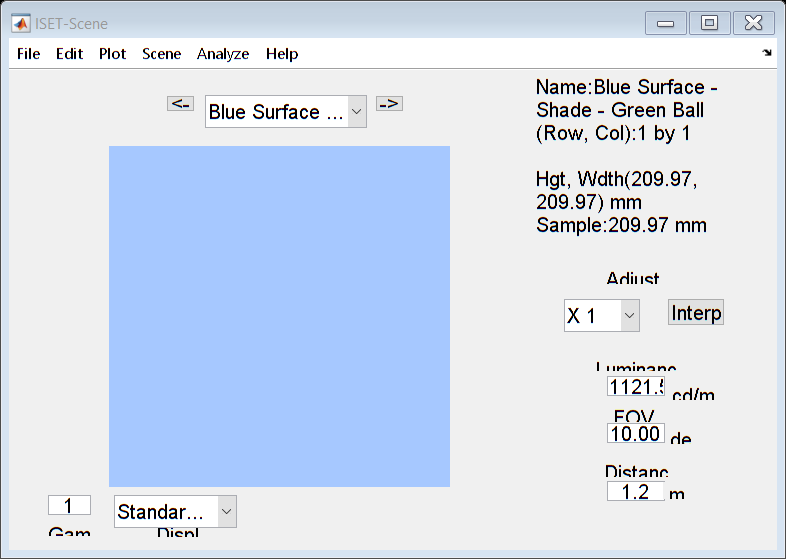

wavelength = 400:10:700;

scene = sceneCreate;
%scene = sceneSet(scene,'wave', wavelength);

illuminant = ieReadSpectra('spd-2022-11-13_blue_line_on_green_surface_in_shade_white_calibration.mat',wavelength);
scene = sceneSet(scene,'illuminantenergy', illuminant);

scene = sceneSet(scene,'name', 'Blue Surface - Shade - Green Ball');
spectral_radiance = zeros(1,1,length(wavelength));
spectral_radiance(:,:,:) = ieReadSpectra('spd-2022-11-13_blue_line_on_green_surface_in_shade_white_calibration.mat',wavelength);

scene = sceneSet(scene,'energy', spectral_radiance);
sceneWindow(scene);